## Sensitivity analysis of frequency response of a Duffing oscillator

Reference: A. Saccani, J. Marconi & P. Tiso. *Sensitivity Analysis of Nonlinear Frequency Response of Defected Structures*, Nonlinear Dynamics [section 3.2.4, figure 10]. PREPRINT (Version 1) available at Research Square [https://doi.org/10.21203/rs.3.rs-1707949/v1](https://doi.org/10.21203/rs.3.rs-1707949/v1) 

Author:     Alexander Saccani, Msc in mechanical engineering, Politecnico di Milano

                Jacopo Marconi, PhD, Politecnico di Milano

Last modified: 5/8/2022

close all
clear
clc

## Set input

compute_stability = true;

% PARAMETER OF THE SYSTEM__________________________________________________
m = 1;      % mass
k1 = 1;     % linear spring
k3 = 0.000; % cubic spring (in the paper example, 0 and 0.015, Fig.10)
d = 0.06;   % damping coefficient
F = 0.25;   % load amplitude

% DEFINITION OF PARAMETER VECTOR AND ITS VARIATION_________________________
% We define the parameter vector. with respect to sensitivity analysis is 
% performed. We define its nominal value and its variation from the nominal
p = k3;             % vector of parameters
dp_all{1} = -0.02;  % absolute parameter variations
dp_all{2} = -0.01;
dp_all{3} = +0.01;
dp_all{4} = +0.02;

% ANALYSIS SETTINGS________________________________________________________
H = 5;              % number of harmonics
method = 'normal';  % method for sensitivity analysis
ord_exp = 2;        % expansion order for sensitivity analysis

## Nominal solution and sensitivity analysis

% nominal solution is computed simulating the system for parameter
% vector p. Sensitivity analysis to parameters is run in parallel with the
% nominal solution

%length of parameter vector
np = length(p);

%number of dofs
n = 1;

% CREATE SYSTEM FOR NlVib__________________________________________________
nonlinear_elements{1} = struct('type', 'cubicspring', 'stiffness', k3);
system = SingleMassOscillator(m, d, k1, nonlinear_elements, F);

% SET PARAMETERS FOR ANALYSIS______________________________________________
om_n = sqrt(k1/m);  % linear eigenfrequency

% set frequency range for analysis
Om_s = 1e-3*om_n;   % start frequency
Om_e = 2*om_n;      % end frequency 

% number of samples for A.F.T.
N = 3*H+1;  % for residual of nonlinear forces 
Ns = 2*N;   % for derivatives of the residual (usually this value has to be greater then N)

%linear solution
omega_lin = linspace(Om_s,Om_e,100);
Q_lin = 1./(-omega_lin.^2*system.M + 1i*omega_lin*system.D + system.K)*F';
Q1 = Q_lin(1);
x0 = zeros(2*H+1,1);
x0(1+(1:2)) = [real(Q1);-imag(Q1)]; 

% define function handle for derivatives in time domain
derFunHandle = @(q)oscillator_derivatives(q,p);

% define postprocessing function for sensitivity analysis
fun_postprocess = @(X) HB_sensitivity(X, system, derFunHandle, np, method,...
                                    ord_exp, Ns);
% define path continuation step size
ds = 0.12; 

% other settings for continuation
Solopt = optimset(optimset(@fsolve),'Display','off',...
        'Jacobian','on');
Sopt = struct('jac','none','dsmax',ds); % analytical Jacobian provided here
Sopt.reversaltolerance = 1;

% RUN ANALYSIS_____________________________________________________________
[Xnom,SolInfo,Sol] = solve_and_continue(x0,...
    @(X) HB_residual(X,system,H,N),...
    Om_s,Om_e,ds,Sopt,fun_postprocess,Solopt);

NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1     1.25001e-42                      1.12e-21               1

Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the 



% create struct array with sensitivities
sens = [Sol.Sens];

% decode nominal solution
Xn = nlvib_decode(Xnom, 0, 0, 'FRF', 'HB', n, H);
% Xn is a struct array with fields 'Q0','Qre','Qim','omega'. 
% Xn.Q0{ij} --> static coefficient A0,  dof i, sample j
% Xn.Qre{ijk} --> real coefficient, dof i, sample j, harmonic k
% Xn.Qim{ijk} --> imaginary coefficient, dof i, sample j, harmonic k
% Xn.omega --> vector of ang. frequencies

if compute_stability
    % stability analysis
    stable_nom = nlvib_StabilityAnalysis(system, Xnom, 'HB', H);
end

A posteriori Floquet stability analysis required 1.0013 s.


## shooting (nominal)

% % Number of time samples per period
% Ntd = 2^8;
% 
% % Initial guess (solution of underlying linear system)
% ys = [real(Q1);-Om_s*imag(Q1)];
% 
% % Solve and continue w.r.t. Om
% % ds = .02;
% % Sopt = struct('Dscale',[1e0*ones(size(ys));Om_s]);%,'dynamicDscale',1);
% Np = 1; % we seek period-one solutions
% [X_shoot,Solinfo] = ...
%     solve_and_continue(ys,...
%     @(X) shooting_residual(X,system,Ntd,Np,'FRF'),...
%     Om_s,Om_e,ds,Sopt);
% 
% % Interpret solver output
% Om_shoot = X_shoot(end,:);
% Ys = X_shoot(1:end-1,:);
% 
% [s, mucrit] = nlvib_StabilityAnalysis(system, X_shoot, 'shooting', H);

## Re-simulate the system for p = p+dp

%initialize output
X1_all = cell(length(dp_all),1);
X2_all = cell(length(dp_all),1);
Xr_all = cell(length(dp_all),1);

%set frequency limit for continuation at different parameter variations
Om_lim = cell(4,1);
Om_lim{1} = [Om_s, Om_e];
Om_lim{2} = [Om_s, Om_e];
Om_lim{3} = [Om_s, Om_e];
Om_lim{4} = [Om_s, Om_e];

%loop 
for ii = 1:length(dp_all)
    
    % actual parameter variation
    dp = dp_all{ii};
    
    % Sensitivity based solution
    % response for p = p + dp computed with 1st and 2nd order sensitivities
    X12 = update_response(Xnom, sens, dp);
    XX1{ii} = X12.lin; %#ok<SAGROW> 
    XX2{ii} = X12.quad; %#ok<SAGROW>
    
    % decode sensitivity based response
    X1 = nlvib_decode(X12.lin, 0, 0, 'FRF', 'HB', n, H); %linear approx.
    X2 = nlvib_decode(X12.quad, 0, 0, 'FRF', 'HB', n, H); %quadratic approx.
    
    % UPDATE SYSTEM FOR NlVib__________________________________________________
    % update stiffness values
    k3_ii = k3 + dp;
    
    % cubic spring
    nonlinear_elements{1} = struct('type', 'cubicspring', 'stiffness', k3_ii);
    
    % generate system
    system = SingleMassOscillator(m, d, k1, nonlinear_elements, F);
    
    % RUN ANALYSIS_____________________________________________________________
    om_n = sqrt(k1/m); % eigenfrequency
    
    % initial guess for continuation (linear approximation)
    Q1 = (-Om_s^2*system.M + 1i*Om_s*system.D + system.K)\F;
    x0 = zeros((2*H+1),1);
    x0(1+(1:2)) = [real(Q1);-imag(Q1)]; 
    
    % set frequency range for analysis
    Om_lim_ii  = Om_lim{ii};
    Om_s = Om_lim_ii(1); %start frequency
    Om_e = Om_lim_ii(2); % end frequency 
    
    % re-simulate the system
    [X,SolInfo,Sol] = solve_and_continue(x0,...
        @(X) HB_residual(X,system,H,N),...
        Om_s,Om_e,ds,Sopt);
    XXr{ii} = X; %#ok<SAGROW> 
    
    % decode re-simulated solution
    Xr = nlvib_decode(X, SolInfo, Sol, 'FRF', 'HB', n, H);
    
    X1_all{ii} = X1;
    X2_all{ii} = X2;
    Xr_all{ii} = Xr;
    
    if compute_stability
        % compute stability
        stable1{ii} = nlvib_StabilityAnalysis(system, XX1{ii}, 'HB', H); %#ok<SAGROW> 
        stable2{ii} = nlvib_StabilityAnalysis(system, XX2{ii}, 'HB', H); %#ok<SAGROW> 
        stable_r{ii} = nlvib_StabilityAnalysis(system, XXr{ii}, 'HB', H); %#ok<SAGROW>
    end
end

NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1     6.10355e-08                      0.000234               1
     1          2     9.12467e-19    0.000247868       8.04e-10               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance,

A posteriori Floquet stability analysis required 1.1784 s.


A posteriori Floquet stability analysis required 1.2751 s.


A posteriori Floquet stability analysis required 1.5672 s.


NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1     1.52589e-08                      0.000117               1
     1          2     1.42039e-20     0.00012373       1.01e-10               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance,

A posteriori Floquet stability analysis required 1.3049 s.


A posteriori Floquet stability analysis required 1.1851 s.


A posteriori Floquet stability analysis required 1.1993 s.


NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1     1.52589e-08                      0.000117               1
     1          2     1.39645e-20    0.000123325          1e-10               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance,

A posteriori Floquet stability analysis required 1.1144 s.


A posteriori Floquet stability analysis required 1.2912 s.


A posteriori Floquet stability analysis required 1.0565 s.


NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1     6.10355e-08                      0.000235               1
     1          2     8.86105e-19    0.000246246       7.99e-10               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance,

A posteriori Floquet stability analysis required 1.1523 s.


A posteriori Floquet stability analysis required 1.1609 s.


A posteriori Floquet stability analysis required 1.237 s.


## plot results

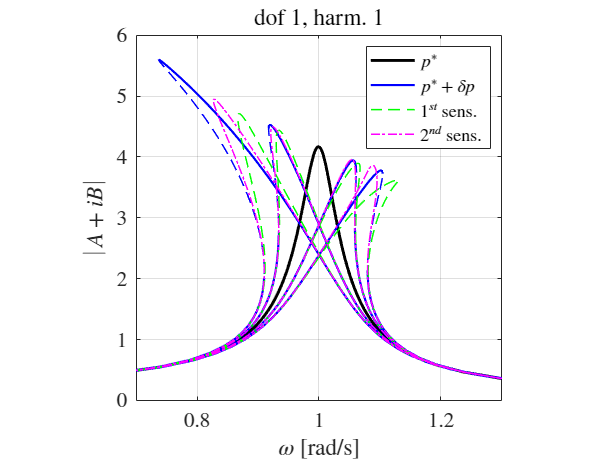

nd = 1;     % dof to plot
harm = 1;   % harmonic to plot

figure

% plot nominal FRC
frc = Xn;
mod = abs(frc.Qre(nd,:,harm) + 1i*frc.Qim(nd,:,harm));
try 
    s = stable_nom; 
catch 
    s = ':'; 
end
smod = mod; smod(s==0) = NaN;
np = plot(frc.omega, smod, 'k', 'LineWidth', 2); % plot only stable sol
hold on
plot(frc.omega, mod, 'k--', 'LineWidth', 1); % plot the full solution

% plot reference variated FRC
for ii = 1 : length(Xr_all)
    frc = Xr_all{ii};
    mod = abs(frc.Qre(nd,:,harm) + 1i*frc.Qim(nd,:,harm));
    try 
        s = stable_r{ii}; 
    catch 
        s = ':'; 
    end
    smod = mod; smod(s==0) = NaN;
    rp = plot(frc.omega, smod,'b','LineWidth',1.5); % plot only stable sol
    plot(frc.omega, mod, 'b--', 'LineWidth', 1); % plot the full solution
end

% plot 1st order approximated FRC
for ii = 1 : length(X1_all)
    frc = X1_all{ii};
    mod = abs(frc.Qre(nd,:,harm) + 1i*frc.Qim(nd,:,harm));
    fp = plot(frc.omega, mod, 'g--', 'LineWidth', 1);
end

% plot second order approximated FRC
for ii = 1 : length(X2_all)
    frc = X2_all{ii};
    mod = abs(frc.Qre(nd,:,harm) + 1i*frc.Qim(nd,:,harm));
    sp = plot(frc.omega, mod, 'm-.', 'LineWidth', 1);
end

% figure style
l = legend([np, rp, fp, sp], {'$p^*$','$p^*+\delta p$', ...
    '$1^{st}$ sens.', '$2^{nd}$ sens.'});
l.Interpreter = 'latex';
xlabel('$\omega$ [rad/s]','Interpreter','latex');
ylabel('$|A + iB|$','Interpreter','latex');
title(['dof ',num2str(nd),', harm. ',num2str(harm)],'Interpreter','latex');
set(gca,'ticklabelinterpreter','latex','fontsize',14)
axis square
axis([0.7,1.3,0,6]);
grid on

## functions

function der = oscillator_derivatives(q,p)
    % (CUBIC TERM ONLY)
    % f=nonlinear force, q=displacement, v=velocity, p=parameter
    % example: dfdp = \partial{f}/\partial{p}

    k_3 = p;
    
    dfdp = q^3;    
    dfdp2 = 0;    
    dfdq = 3*k_3*q^2;
    dfdqdp = 3*q^2;    
    dfdq2 = 6*k_3*q;
    
    dfdv = 0;    
    dfdv2 = 0;    
    dfdvdp = 0;    
    dfdqdv = 0;
        
    dfcdp = 0; %derivative of load (cosine)
    
    der.dfdp = dfdp;
    der.dfdp2 = dfdp2;
    der.dfdqdp = dfdqdp;
    der.dfdq = dfdq;
    der.dfdq2 = dfdq2;    
    der.dfdv = dfdv;
    der.dfdv2 = dfdv2;
    der.dfdvdp = dfdvdp;
    der.dfdqdv = dfdqdv;    
    der.dfcdp = dfcdp;
end